% Author: Kenneth H.L. Ho
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

## Access the image directly from SSBD database into MATLAB

% Access SSBD and retrieve image id = 1, Z = 30, t = 0
k_img = ssbd.image(1, 30, 0); 

id: 1, z: 30, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0


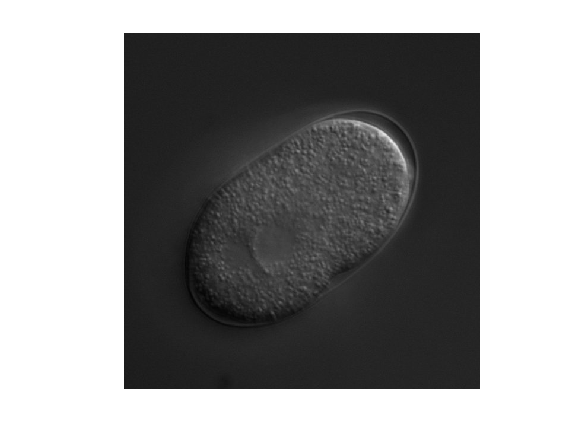

imshow(k_img)

% Accessing quantitative data from the SSBD database
% here we access the data with bdml_ID = 4ed09fa3-7650-45a9-ac55-426980aa7d0a
% ssbd.bd5coords(bdml_id, time, offset, limit)
% 
coords = ssbd.bd5coords("4ed09fa3-7650-45a9-ac55-426980aa7d0a", 0, 0, 20)

bdmlid=4ed09fa3-7650-45a9-ac55-426980aa7d0a, timept=0, offset=0, limit=20
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&ts=0&offset=0&limit=20



coords = struct with fields:
       meta: [1×1 struct]
    objects: [20×1 struct]


disp(coords.meta)

          limit: 20
           next: '/SSBD/api/v3/bd5coords/?bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&format=json&limit=20&ts=0&offset=20'
         offset: 0
       previous: []
    total_count: 9691



disp(coords.objects)

  20×1 struct array with fields:

    entity
    id
    label
    radius
    sid
    t
    x
    y
    z



coords.objects.x

ans = '194'

ans = '193'

ans = '193'

ans = '192'

ans = '192'

ans = '192'

ans = '191'

ans = '190'

ans = '189'

ans = '188'

ans = '187'

ans = '186'

ans = '185'

ans = '184'

ans = '183'

ans = '182'

ans = '181'

ans = '180'

ans = '179'

ans = '179'

coords.objects.y

ans = '350'

ans = '351'

ans = '352'

ans = '353'

ans = '354'

ans = '355'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '355'

ans = '355'

ans = '355'

ans = '355'

ans = '356'

ans = '357'

coords.objects(2)

ans = struct with fields:
    entity: 'line'
        id: '1000'
     label: 'P0'
    radius: []
       sid: 0
         t: '1'
         x: '193'
         y: '351'
         z: '11'


coords.objects(2).x

ans = '193'

size(coords.objects)

ans =     20     1


scale = ssbd.bd5scaleunit("4ed09fa3-7650-45a9-ac55-426980aa7d0a")

bdmlid=4ed09fa3-7650-45a9-ac55-426980aa7d0a
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5scaleunit/?format=json&bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&offset=0&limit=1



scale = struct with fields:
       meta: [1×1 struct]
    objects: [1×1 struct]


scale.meta

ans = struct with fields:
          limit: 1
           next: []
         offset: 0
       previous: []
    total_count: 1


scale.objects

ans = struct with fields:
    dimension: '3D+T'
        sUnit: 'micrometer'
       tScale: '40'
        tUnit: 'second'
       xScale: '0.105'
       yScale: '0.105'
       zScale: '0.5'


scale.objects.xScale

ans = '0.105'